# HDI: Patterns and Trends

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 12/2020

Description: Identify trends and patterns

clc
clear
close all


load ../Data/Data_Area_N.mat
load ../Data/Data_EIA_H.mat
load ../Data/Data_Indicators.mat
load ../Data/Area_Country.mat

CO2_N=Indicators.GHG_N;
Exp_N=Indicators.Exp_N;
GDP_N=Indicators.GDP_N;
HDI_N=Indicators.HDI_N;
Land_N=Indicators.Land_N;
Mat_N=Indicators.Mat_N;
Ren_N=Indicators.Ren_N;
Water_N=Indicators.Water_N;
Labels=Data_EIA_H.Labels;
Labels(53)={'Cote dIvoire'};
Score=Areas.Area_Opt;

year=1990:2015;
% Here set the year 6 is 1995
yo=26;
Pop=Data_EIA_H.Population(:,yo);
% Print 
P='F';% 'T' prints


Ind_S=[];
for j=yo
    m=j;
    for n= 1:231
   
        Y=[GDP_N(n,m),CO2_N(n,m),...
          Exp_N(n,m),Ren_N(n,m),Water_N(n,m),Land_N(n,m),...
          Mat_N(n,m),HDI_N(n,m),GDP_N(n,m)]; % Optimized
    Ind_S=[Ind_S;Y];
        
    end
end

[rows, columns] = find(isnan(Ind_S));
Clean=unique(rows);
Score_Y=Score(:,yo);

## Filter by area or

Area_C=AreaCountry.totalAreaInSquareKilometres(1:end);
F_A=find(Area_C<100000);
Clean=unique([Clean;F_A]);

## Clean and Table

Score_Y(Clean)=[];
Labels(Clean)=[];
Ind_S(Clean,:)=[];
Num=1:size(Score_Y);
Num=Num';

Tab=table(Labels,Num,Score_Y);
CO2_N(Clean,:)=[];
Exp_N(Clean,:)=[];
GDP_N(Clean,:)=[];
HDI_N(Clean,:)=[];
Land_N(Clean,:)=[];
Mat_N(Clean,:)=[];
Ren_N(Clean,:)=[];
Water_N(Clean,:)=[];
Pop(Clean)=[];

## Make Categorical Classification


% CO2
CO2_cat=categorical([]);
H=find(CO2_N>=1);
M=find(CO2_N<1 & CO2_N>0.4);
L=find(CO2_N<=0.4);
N=isnan(CO2_N);
CO2_cat(L)='L';
CO2_cat(M)='M';
CO2_cat(H)='H';
CO2_cat(N)='NaN';
CO2_cat=reshape(CO2_cat,[length(Score_Y) 26]);

% Energy
Exp_cat=categorical([]);
H=find(Exp_N>=0.9);
M=find(Exp_N<0.9 & Exp_N>0.5);
L=find(Exp_N<=0.5);
N=isnan(Exp_N);
Exp_cat(L)='L';
Exp_cat(M)='M';
Exp_cat(H)='H';
Exp_cat(N)='NaN';
Exp_cat=reshape(Exp_cat,[size(Score_Y) 26]);

% GDP
GDP_cat=categorical([]);
H=find(GDP_N>=1);
M=find(GDP_N<1 & GDP_N>0.4);
L=find(GDP_N<=0.4);
N=isnan(GDP_N);
GDP_cat(L)='L';
GDP_cat(M)='M';
GDP_cat(H)='H';
GDP_cat(N)='NaN';
GDP_cat=reshape(GDP_cat,[size(Score_Y) 26]);

% HDI
HDI_cat=categorical([]);
H=find(HDI_N>=0.8);
M=find(HDI_N<0.8 & HDI_N>0.55);
L=find(HDI_N<=0.55);
N=isnan(HDI_N);
HDI_cat(L)='L';
HDI_cat(M)='M';
HDI_cat(H)='H';
HDI_cat(N)='NaN';
HDI_cat=reshape(HDI_cat,[size(Score_Y) 26]);

% Arable Land
Land_cat=categorical([]);
H=find(Land_N>=1);
M=find(Land_N<1 & Land_N>0.4);
L=find(Land_N<=0.4);
N=isnan(Land_N);
Land_cat(L)='L';
Land_cat(M)='M';
Land_cat(H)='H';
Land_cat(N)='NaN';
Land_cat=reshape(Land_cat,[size(Score_Y) 26]);

% Material
Mat_cat=categorical([]);
H=find(Mat_N>=1);
M=find(Mat_N<1 & Mat_N>0.5);
L=find(Mat_N<=0.5);
N=isnan(Mat_N);
Mat_cat(L)='L';
Mat_cat(M)='M';
Mat_cat(H)='H';
Mat_cat(N)='NaN';
Mat_cat=reshape(Mat_cat,[size(Score_Y) 26]);

% Renewable
Ren_cat=categorical([]);
H=find(Ren_N>=0.5);
M=find(Ren_N<0.5 & Ren_N>0.25);
L=find(Ren_N<=0.25);
N=isnan(Ren_N);
Ren_cat(L)='L';
Ren_cat(M)='M';
Ren_cat(H)='H';
Ren_cat(N)='NaN';
Ren_cat=reshape(Ren_cat,[size(Score_Y) 26]);

% Water
Water_cat=categorical([]);
H=find(Water_N>=1);
M=find(Water_N<1 & Water_N>0.5);
L=find(Water_N<=0.5);
N=isnan(Water_N);
Water_cat(L)='L';
Water_cat(M)='M';
Water_cat(H)='H';
Water_cat(N)='NaN';
Water_cat=reshape(Water_cat,[size(Score_Y) 26]);

## Here creates the filters


% GDP
GDP_H=find(GDP_cat(:,yo)=='H');
GDP_M=find(GDP_cat(:,yo)=='M');
GDP_L=find(GDP_cat(:,yo)=='L');
% HDI
HDI_H=find(HDI_cat(:,yo)=='H');
HDI_M=find(HDI_cat(:,yo)=='M');
HDI_L=find(HDI_cat(:,yo)=='L');
% Water
Wat_H=find(Water_cat(:,yo)=='H');
Wat_M=find(Water_cat(:,yo)=='M');
Wat_L=find(Water_cat(:,yo)=='L');
% Land
Land_L=find(Land_cat(:,yo)=='L');
Land_M=find(Land_cat(:,yo)=='M');
Land_H=find(Land_cat(:,yo)=='H');
% Energy
En_H=find(Exp_cat(:,yo)=='H');
En_M=find(Exp_cat(:,yo)=='M');
En_L=find(Exp_cat(:,yo)=='L');
%CO2
CO2_H=find(CO2_cat(:,yo)=='H');
CO2_M=find(CO2_cat(:,yo)=='M');
CO2_L=find(CO2_cat(:,yo)=='L');
% Material Footprint
Mat_H=find(Mat_cat(:,yo)=='H');
Mat_M=find(Mat_cat(:,yo)=='M');
Mat_L=find(Mat_cat(:,yo)=='L');
% Renewables
Ren_H=find(Ren_cat(:,yo)=='H');
Ren_M=find(Ren_cat(:,yo)=='M');
Ren_L=find(Ren_cat(:,yo)=='L');


% Here Specify the variable analized
% High
RH=HDI_H;
AP=find(Score_Y>=0.35);
RH=intersect(RH,AP);

RL=HDI_H;
AP=find(Score_Y<=0.25);
RL=intersect(RL,AP);

RM=HDI_H;
AP=find(Score_Y<0.35 & Score_Y>0.25 );
RM=intersect(RM,AP);

% Middle
MH=HDI_M;
AP=find(Score_Y>=0.35);
MH=intersect(MH,AP);

MM=HDI_M;
AP=find(Score_Y<0.35 & Score_Y>0.25 );
MM=intersect(MM,AP);

ML=HDI_M;
AP=find(Score_Y<=0.25);
ML=intersect(ML,AP);

% Low
PH=HDI_L;
AP=find(Score_Y>=0.35);
PH=intersect(PH,AP);

PM=HDI_L;
AP=find(Score_Y<0.35 & Score_Y>0.25 );
PM=intersect(PM,AP);

PL=HDI_L;
AP=find(Score_Y<=0.25);
PL=intersect(PL,AP);

## Rich

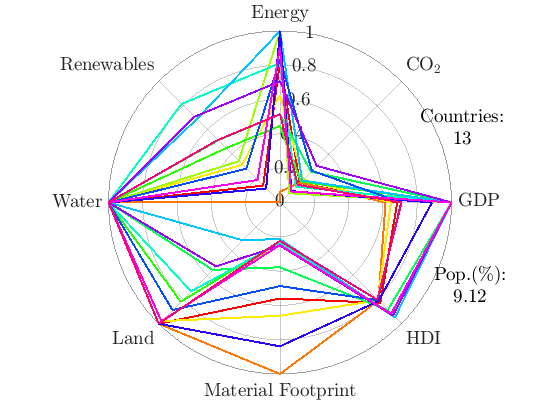

% High
Pop_RH=nansum(Pop(RH))/Pop(1)*100;
N=length(RH); 
C = hsv(N);
i=0;
figure
for n=RH'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(RH));
SP=sprintf('%.2f',Pop_RH);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Rich_H.eps')
end

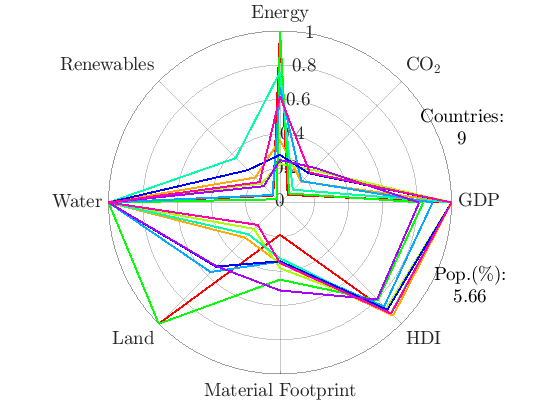


% Middle

Pop_RM=nansum(Pop(setdiff(RM,1)))/Pop(1)*100;
N=length(RM); 
C = hsv(N);
i=0;
figure
for n=RM'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(RM));
SP=sprintf('%.2f',Pop_RM);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");


if P=='T'
    print('-depsc2','-r400','H_Rich_M.eps')
end

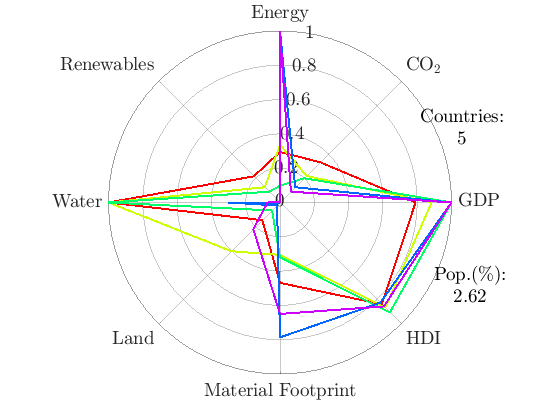


% Low
Pop_RL=nansum(Pop(setdiff(RL,1)))/Pop(1)*100;
N=length(RL); 
C = hsv(N);
i=0;
figure
for n=RL'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(RL));
SP=sprintf('%.2f',Pop_RL);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Rich_L.eps')
end

## Middle

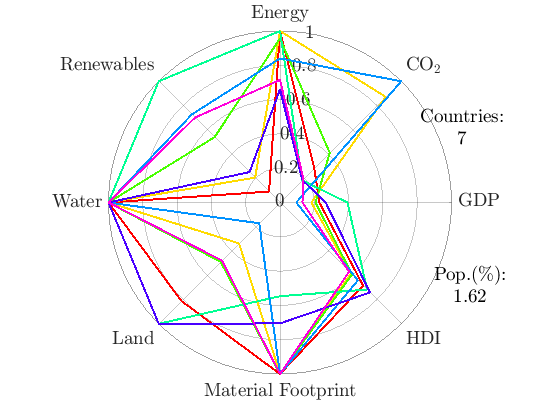

% High
Pop_MH=nansum(Pop(setdiff(MH,1)))/Pop(1)*100;
N=length(MH); 
C = hsv(N);
i=0;
figure
for n=MH'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(MH));
SP=sprintf('%.2f',Pop_MH);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Middle_H.eps')
end

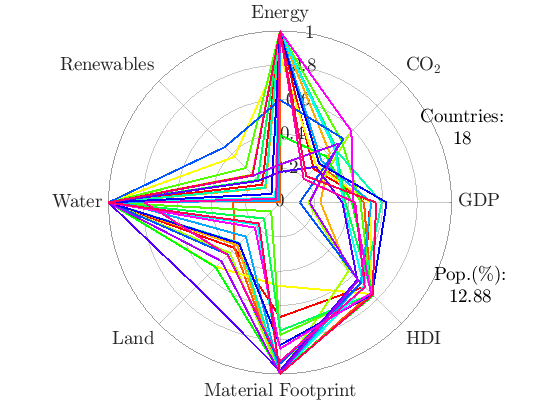


% Middle
Pop_MM=nansum(Pop(setdiff(MM,1)))/Pop(1)*100;
N=length(MM); 
C = hsv(N);
i=0;
figure
for n=MM'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(MM));
SP=sprintf('%.2f',Pop_MM);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Middle_M.eps')
end

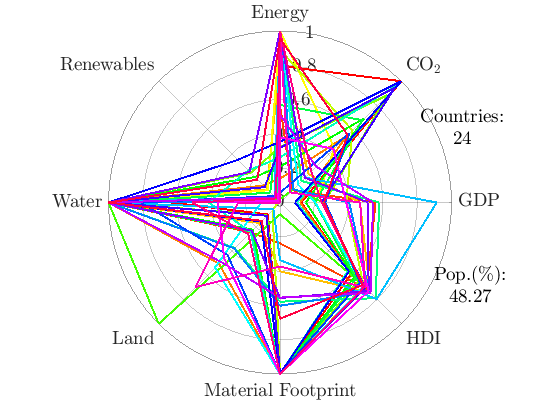


% Low
Pop_ML=nansum(Pop(setdiff(ML,1)))/Pop(1)*100;
N=length(ML); 
C = hsv(N);
i=0;
figure
for n=ML'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(ML));
SP=sprintf('%.2f',Pop_ML);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Middle_L.eps')
end

## Poor

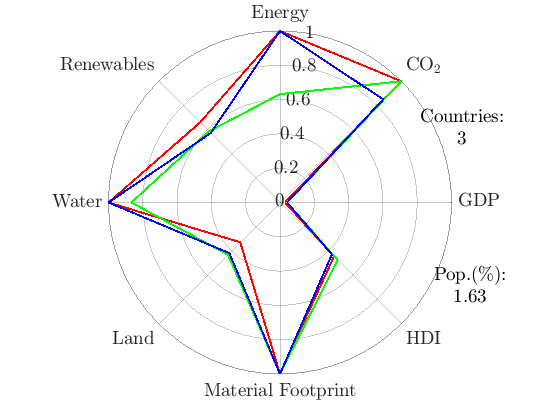

% High
Pop_PH=nansum(Pop(setdiff(PH,1)))/Pop(1)*100;
N=length(PH); 
C = hsv(N);
i=0;
figure
for n=PH'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(PH));
SP=sprintf('%.2f',Pop_PH);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Poor_H.eps')
end

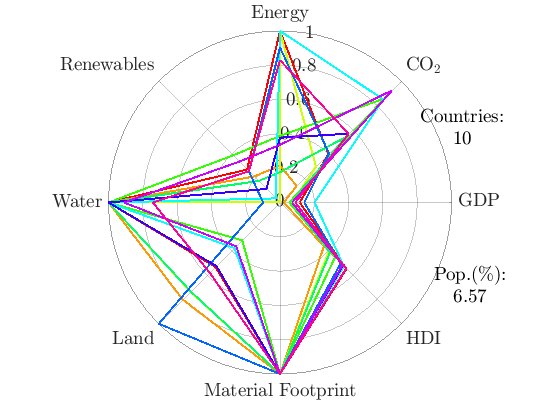


% Middle

Pop_PM=nansum(Pop(setdiff(PM,1)))/Pop(1)*100;
N=length(PM); 
C = hsv(N);
i=0;
figure
for n=PM'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(PM));
SP=sprintf('%.2f',Pop_PM);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Poor_M.eps')
end

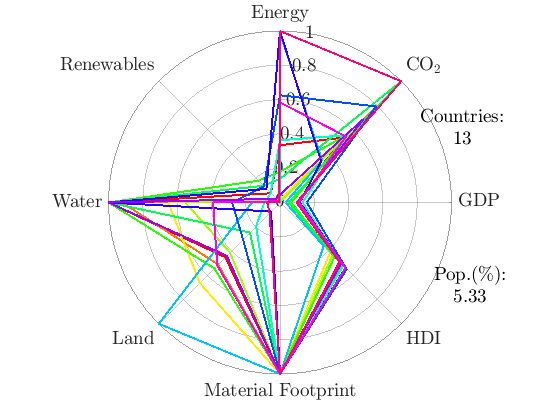


% Low
Pop_PL=nansum(Pop(setdiff(PL,1)))/Pop(1)*100;
N=length(PL); 
C = hsv(N);
i=0;
figure
for n=PL'
    i=i+1;
    Values=Ind_S(n,:);
    X=[0,45,90,135,180,225,270,315,360]*pi/180;
    Labeltheta={'GDP','$$\mathrm{CO_2}$$','Energy','Renewables','Water','Land',...
        'Material Footprint','HDI'};
    polarplot(X,Values,'Color',C(i,:),'linewidth',1.5)
    hold on
    thetaticks(0:45:315)
    thetaticklabels(Labeltheta)
    set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
    
end
% String
ST=sprintf('%d', length(PL));
SP=sprintf('%.2f',Pop_PL);
annotation('textbox', [0.825 0.75 0 0], 'String', {'Countries:';ST}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");
annotation('textbox', [0.84 0.375 0 0], 'String', {'Pop.(\%):';SP}, 'FitBoxToText', true,...
    'EdgeColor','none','Interpreter',"latex",'FontSize',14,'HorizontalAlignment',"center");

if P=='T'
    print('-depsc2','-r400','H_Poor_L.eps')
end